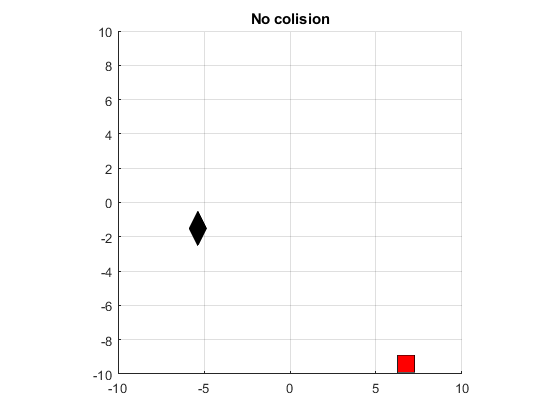

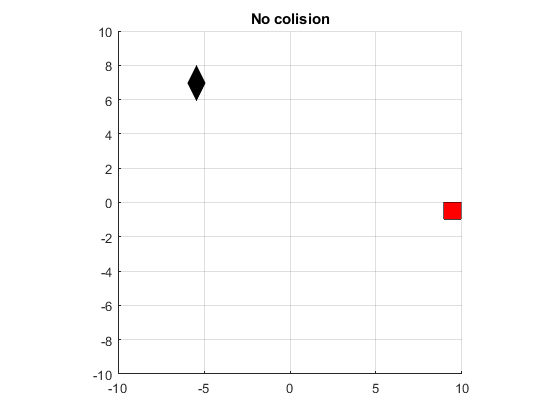

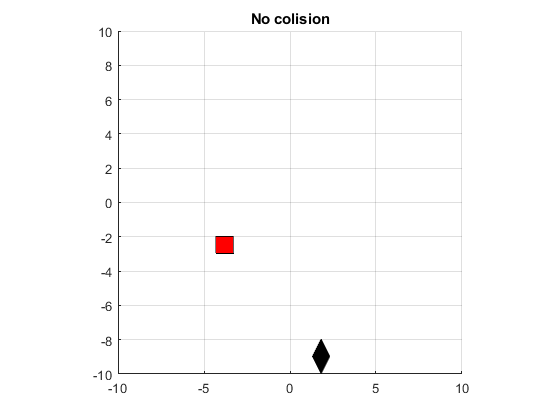

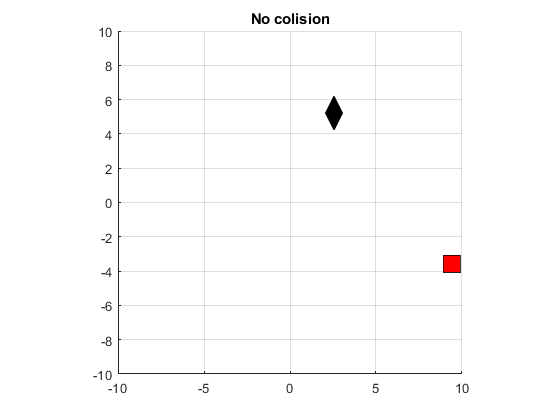

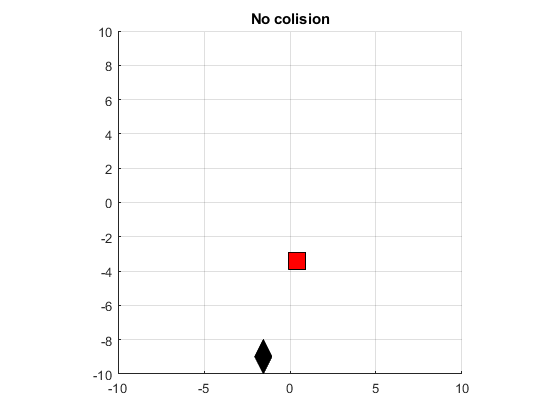

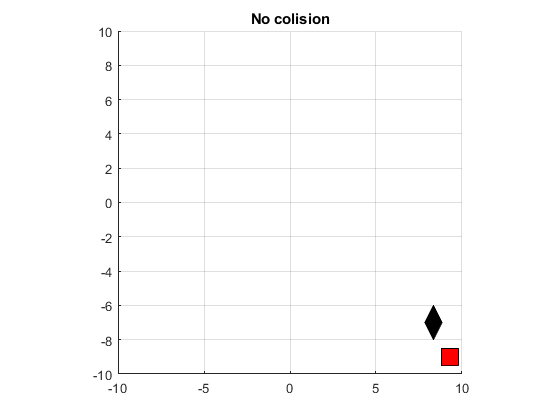

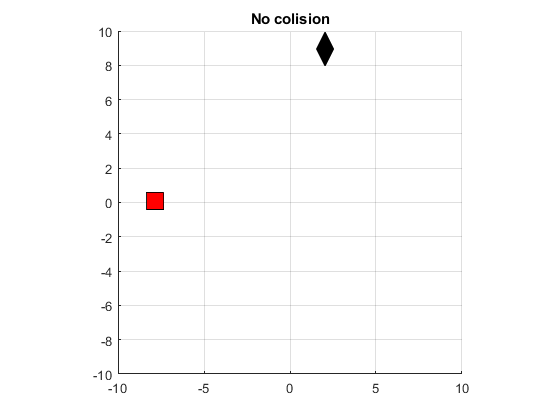

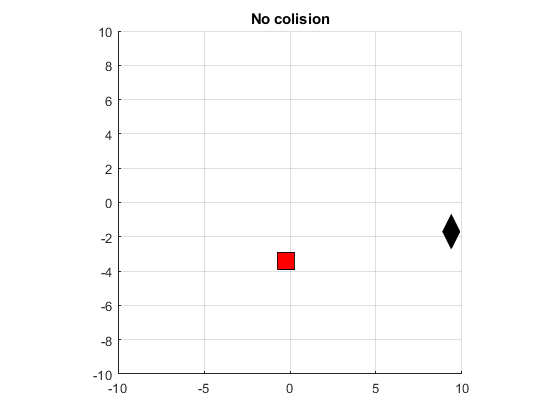

d = 0;
while ~d
    close all
    random = randi([-10,10],8,1); % genera vectores de posicion y velocidad aletorios
    x1 = [0 0.5 1 0.5]; % coordenadas x de la primer figura
    y1 = [0 1 0 -1]; % coordenadas y de la primer figura
    x2 = [0 0 1 1]; % coordenadas x de la segunda figura
    y2 = [0 1 1 0]; % coordenadas y de la segunda figura
    g1 = hgtransform; % se crea una matriz de transformacion para la primer figura
    g2 = hgtransform; % se crea una matriz de transformacion para la segunda figura
    fig1 = patch('XData',x1,'YData',y1,'parent',g1); % se genera la primera figura
    fig2 = patch('XData',x2,"YData",y2,'FaceColor','red','parent',g2); % se genera la segunda figura
    x = [1, 0, 0]; % vector unitario x en 3d para aplicar en la transformacion
    y = [0, 1, 0]; % vector unitario y en 3d para aplicar en la transformacion
    X = [1,0]; % vector unitario x en 2d para aplicar en el producto punto
    Y = [0,1]; % vector unitario y en 2d para aplicar en el producto punto
    axis equal
    grid on
    xlim([-10,10]);
    ylim([-10,10]);
    transfig1 = zeros(4,2);
    transfig2 = zeros(4,2);
    for i = linspace(0,3,150)
        g1.Matrix = makehgtform("translate",x*random(1)*i + y*i*random(2) + [random(3),random(4),0]); % velocidad de la figura 1 
        g2.Matrix = makehgtform("translate",x*random(5)*i + y*i*random(6) + [random(7),random(8),0]); % velocidad de la figura 2
        for j=1:4
            transfig1(j,:) = [dot(X,fig1.Vertices(j,:)+g1.Matrix(1,4)), dot(Y,fig1.Vertices(j,:)+g1.Matrix(2,4))];% calculo del producto punto para el SAT
            transfig2(j,:) = [dot(X,fig2.Vertices(j,:)+g2.Matrix(1,4)), dot(Y,fig2.Vertices(j,:)+g2.Matrix(2,4))];% calculo del producto punto para el SAT
        end
        % se encuentran los minimos y maximos para verificar si hubo o no
        % colision
        fig1min = min(transfig1); 
        fig1max = max(transfig1);
        fig2min = min(transfig2);
        fig2max = max(transfig2);
        if fig1min(1,1) < -10 || fig1max(1,1) > 10 || fig2min(1,1) < -10 || fig2max(1,1) > 10 % se verifica si hubo colision con el eje x
            title('Colision con eje x')
    
            break
        elseif fig1min(1,2) < -10 || fig1max(1,2) > 10 || fig2min(1,2) < -10 || fig2max(1,2) > 10 % se verifica si hubo colision con el eje y
            title('Colision con eje y')
            break
        elseif fig1max(1,1) < fig2min(1,1) || fig1min(1,1) > fig2max(1,1) % se verifica que el eje x sea un eje que separa las figuras
            title('No colision')
            drawnow
        elseif fig1max(1,2) < fig2min(1,2) || fig1min(1,2) > fig2max(1,2) % se verifica que el eje y 
            title('No colision')
            drawnow
        else
            title('Colision!!')
            %relvel = x*random(1)*i + y*i*random(2)-x*random(5)*i + y*i*random(6)
            d = 1;
            break
        end
    end
end